# 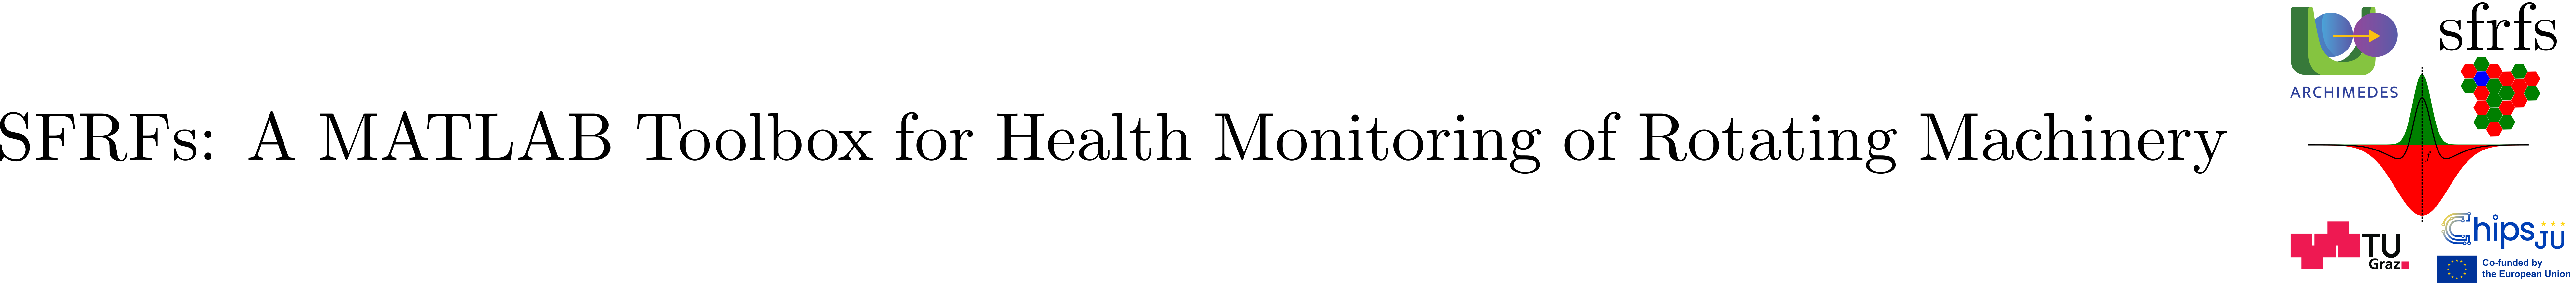

# **EnsembleProcessor (Abstract)**

## Summary

Abstract base class defining the interface and core functionality for processing ensembles of data using parallel execution.

Key features:

- Manages a specified number of parallel workers to process ensemble members efficiently.

- Requires subclasses to implement `getProcessParams` method, returning struct parameters necessary for processing.

- Holds an `EnsembleBroker` instance to access ensemble data files and metadata.

- Provides a `process` method that applies a given function handle to each ensemble member file in parallel using MATLAB's `parfor`.

- Includes robust error handling with aggregated exception reporting from parallel workers.

- Automatically manages parallel pool setup based on the configured number of workers.

- Logs detailed processing information for traceability and debugging.

This class establishes a standardized, extensible foundation for parallel ensemble processing workflows within the toolbox.

## Description

`EnsembleProcessor` is an abstract base class that provides a standardized framework for processing ensembles of data using parallel execution. It manages an [EnsembleBroker](matlab:open('./EnsembleBroker.mlx')) instance for accessing ensemble members, handles the configuration of parallel workers, and ensures robust execution with error aggregation and logging. Subclasses implement the `getProcessParams` method to supply all parameters required for processing, while the base class handles iteration over ensemble members and the application of user-defined processing functions in parallel. This design enables consistent, efficient, and traceable ensemble workflows within the toolbox.

### Properties

### Abstract methods

### Concrete methods

## Notes

- The class **cannot be instantiated directly** because it is abstract. Subclasses must implement all abstract methods, a reference implementation can be found in [FFTEnsembleProcessor](matlab:open('./FFTEnsembleProcessor.mlx')).

- The `process` method automatically sets up a parallel pool if none exists.

- Detailed error messages are aggregated from all workers and logged using `SFRFsLogger`.

## API documentation

### MATLAB help

help EnsembleProcessor

  EnsembleProcessor Abstract base for ensemble processing classes.
 
    Defines the interface for classes that process ensembles using
    parallel workers.
 
  Properties:
    numWorkers           Number of parallel workers to use 
                         (positive integer, default: 2).
 
    ensemble             Ensemble Broker object.
 
  Methods (Abstract):
    getProcessParams     Return a struct with required parameters.
 
  Methods:
    process              Apply a function handle to ensemble members using
                         parallel execution.

    Documentation for EnsembleProcessor
       doc EnsembleProcessor




% Get help for specific functions, for example:
help EnsembleProcessor.process

 PROCESS Process ensemble members using a provided compute 
  handle.
    process(obj, computeHandle) processes all members in the 
    ensemble, applying the function handle 'computeHandle' to 
    each member. Parallel or sequential execution is determined 
    by the number of workers.
 
    Input Arguments:
      obj           - EnsembleProcessor instance.
      computeHandle - Function handle to apply to each member,
                      e.g., 
                      @(tbl, params) SubClass.compute(...
                            tbl, params)
 
    Example (make compute Static):
      processor.process(@(tbl, params) ...
        SubClass.compute(tbl, params));
 
    See also: parfor, EnsembleProcessor



### MATLAB documentation

doc EnsembleProcessor

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

The source of the class is available in [EnsembleProcessor](matlab:open('../../EnsembleProcessor.m'))`.`

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).